# **Experimental Evaluation of Single-Carrier Alamouti System**

The code below uses the DSP associated with the single-carrier Alamouti system to recover transmitted symbols in 16-QAM

% Setup
clearvars
addpath ExperimentalDataMe
addpath ExperimentalDataBence

load('exp_data_1e-2.mat');
% load('capture_50G_run6_-22dBm.mat');
load('capture_50G_down_b2b_3dbatt_received-19dBm_run2.mat')
load('RCOS.mat')

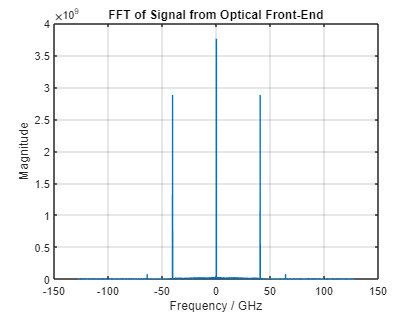

% Frequency Recovery

Fs = 256e9; % Sampling frequency
Fpass = 25.94e9; % Frequency offset
t = (0:length(ch1)-1)/Fs; % Time vector
freq_arr = [-1*length(ch1)/2 : length(ch1)/2 - 1]*Fs/length(ch1); % Frequency vector

fft_passband = fftshift(fft(ch1));

% Using exponential shift
baseband_sig_exp = (ch3.').*exp(1i*2*pi*Fpass*t);
fft_baseband_exp = fftshift(fft(baseband_sig_exp));

% Using circshift
delta = 10; % to cut out the DC component from analysis
spec = fft(ch3);
[~,index] = max(abs(spec(delta+1:end-delta)));
shift  = delta + index;
shifted_spec = circshift(spec,shift);
baseband_sig_circ = ifft(shifted_spec);

% Plotting the spectrum of the received signal
figure;
plot(freq_arr*1e-9, abs(fft_passband))
title('FFT of Signal from Optical Front-End');
xlabel('Frequency / GHz');
ylabel('Magnitude');
grid on

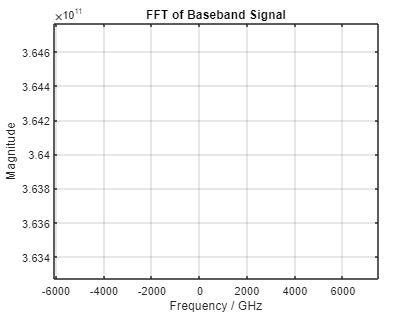

% subplot(3,1,2);
% plot(freq_arr*1e-9, abs(fft_baseband_exp));
% title('FFT of baseband signal - exp');
% xlabel('Frequency / GHz');
% ylabel('Magnitude');
figure;
plot(freq_arr*1e-9, abs(fftshift(fft(baseband_sig_circ))));
title('FFT of Baseband Signal');
xlabel('Frequency / GHz');
ylabel('Magnitude');
grid on

% Resampling the received signal from 256 GSa/s to 100 GSa/s

resampled_sig = resample(baseband_sig_circ, 100, 256);

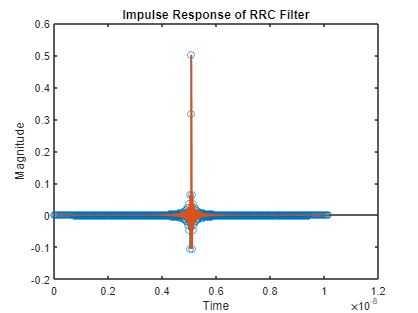

% Matched Filtering
SpS = 2;
filterSpan = (length(a) - 1)/2;
filtered_sig = upfirdn(resampled_sig, a, 1, 1);

% Interpolating Filter for plotting
t_filter = [0:length(a) - 1]/100e9;
filterResponse_t_interp = [0:0.25:length(a)-1]/100e9;
filterResponse_interp = interp1(t_filter, a, filterResponse_t_interp, "spline");

% Plotting RRC filter used
figure;
stem(t_filter, a, '-o')
hold on
plot(filterResponse_t_interp, filterResponse_interp)
title('Impulse Response of RRC Filter')
xlabel('Time')
ylabel('Magnitude')

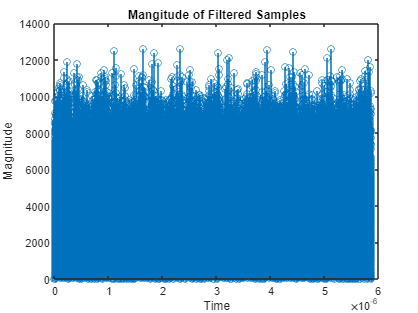


% Plotting magnitude of samples of the filtered signal
t_sig = [0:length(filtered_sig) - 1]/100e9;
figure;
stem(t_sig, abs(filtered_sig), '-o')
hold on
title(['Mangitude of Filtered Samples'])
xlabel('Time')
ylabel('Magnitude')

% Frame Synchronisation

% Finding samples to extract using cross-correlation

[c,lags] = xcorr(filtered_sig, repelem(s_qam, SpS, 1));

synch_index = lags(c == max(c))

synch_index = 346676


% Plotting cross-correlation
% figure
% stem(lags,c)
% title('Cross-correlation for frame synchronisation')
% xlabel('Shift')
% ylabel('Magnitude')

% Extracting synchronised samples

synchronised_sig = filtered_sig(synch_index:synch_index + SpS*length(s_qam)-1,:);

% Normalising the extracted samples
norm_sig = synchronised_sig/max(abs(synchronised_sig));

% CD compensation
Rs=50e9;
linkLength = 40e3;
D = 17;
CLambda = 1550e-9;
c = 299792458; % Speed of light in m/s

N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length

N_CD = 29

N_FFT = 2^10

N_FFT = 1024

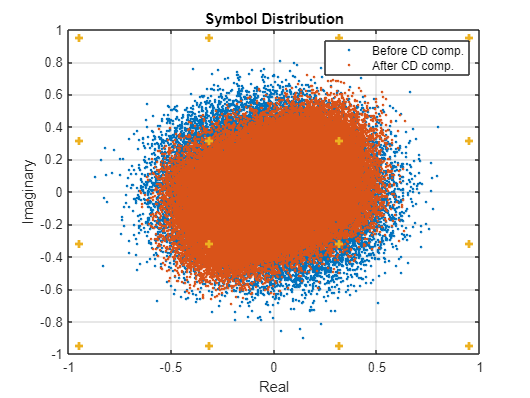


signal_CDC = OverlapSaveCDC(norm_sig, D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);

% Visualising symbol distribution
figure;
plot(norm_sig, '.');
hold on
title("Symbol Distribution")
plot(signal_CDC, '.');
plot(s_qam/sqrt(10), '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before CD comp.", "After CD comp.")
grid on
hold off

% Adaptive Equalization
% NTaps = 60; NRemoveF = 25000; NRemoveB = 6000; N1 = 16000; Mu_T = 1e-4; Mu_DD = Mu_T; Mu_p=2e-2;
NTaps = 50; NRemoveF = 10000; NRemoveB = 2000; N1 = 8000; Mu_T = 2e-2; Mu_DD = Mu_T; Mu_p=2e-2;

trainSymbs = s_qam/sqrt(10);
[equalizedSymbs, pQAM, w11QAM, w12QAM, w21QAM, w22QAM, errQAM] = AdapEqualizerAlamouti(signal_CDC, trainSymbs, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Shaped

% Visualising filter variable evolution
plot([1:size(pQAM)], w11QAM', '-');

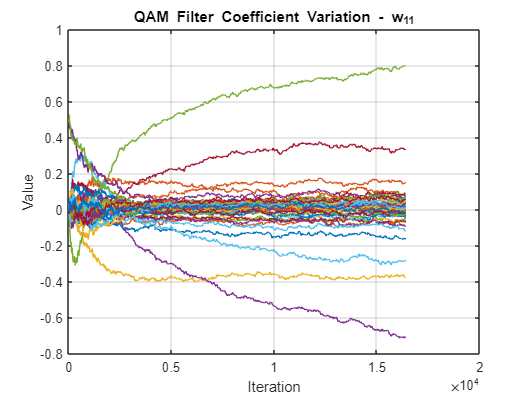

title("QAM Filter Coefficient Variation - w_{11}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w12QAM', '-');

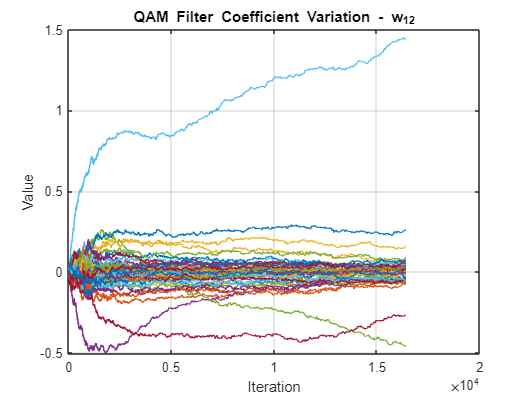

title("QAM Filter Coefficient Variation - w_{12}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w21QAM', '-');

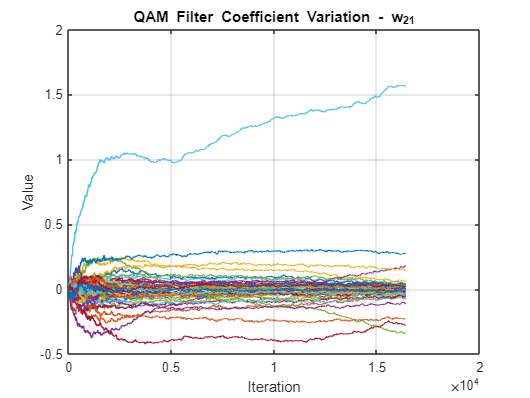

title("QAM Filter Coefficient Variation - w_{21}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w22QAM', '-');

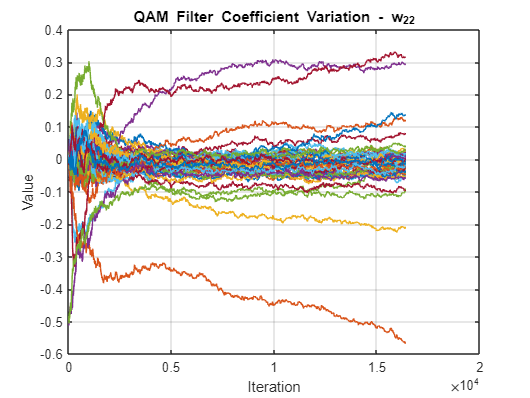

title("QAM Filter Coefficient Variation - w_{22}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], pQAM, '-');

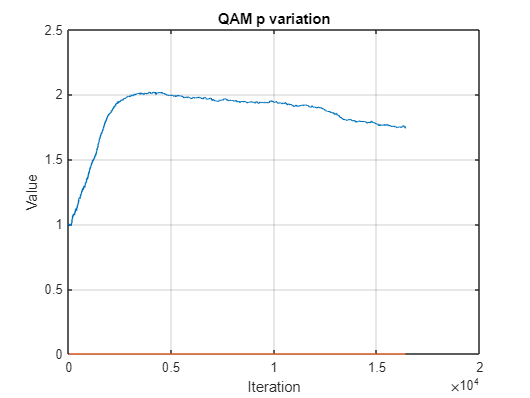

title("QAM p variation")
xlabel("Iteration")
ylabel("Value")
grid on

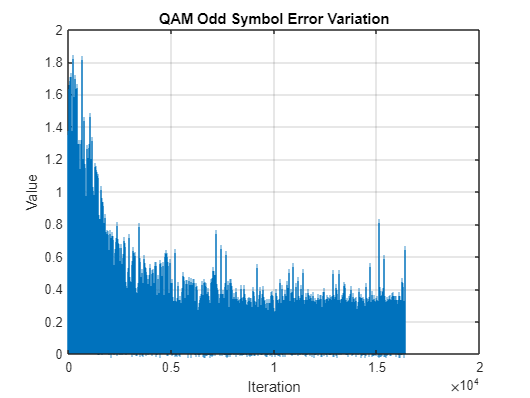


stem([1:size(errQAM(:,1))], abs(errQAM(:,1)), '|');
title("QAM Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

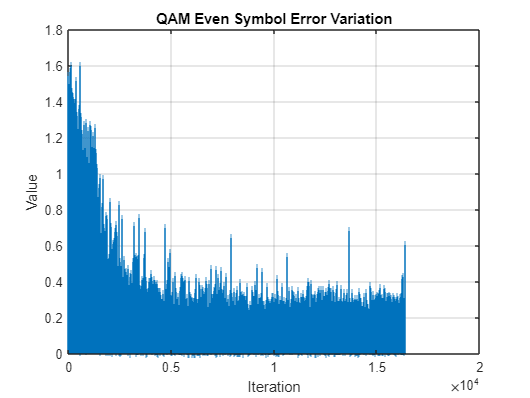


stem([1:size(errQAM(:,2))], abs(errQAM(:,2)), '|');
title("QAM Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

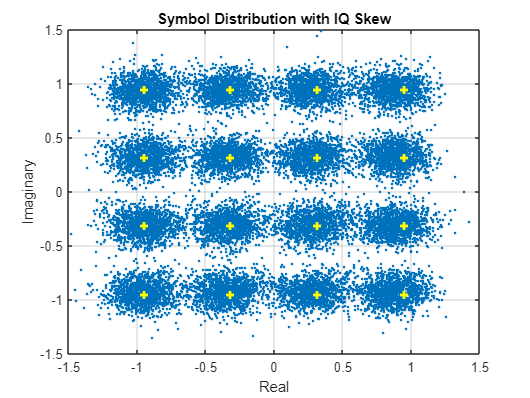


plot(equalizedSymbs(NRemoveF+1:end-NRemoveB), '.', LineWidth=3);
hold on
plot(s_qam/sqrt(10), 'y+', LineWidth=2);
title("Symbol Distribution with IQ Skew")
xlabel("Real")
ylabel("Imaginary")
xlim([-1.5, 1.5])
ylim([-1.5, 1.5])
grid on
hold off

% Decision and decoding before IQ skew compensation

sourceInts = qamdemod(s_qam(NRemoveF+1:end-NRemoveB,1), 16);
sourceBits = int2bit(sourceInts, 4);

EqualizedInts = qamdemod(equalizedSymbs(NRemoveF+1:end-NRemoveB,1), 16, UnitAveragePower=true);
EqualizedBits = int2bit(EqualizedInts, 4);

[~, BER] = biterr(sourceBits, EqualizedBits)

BER = 0.0063

% IQ skew compensation
